cd(fileparts(matlab.desktop.editor.getActiveFilename))
addpath('..\helper\')

simParameters.CarrierFrequency = 27e9; % 2.18e9; %19e9; % 2.18e9;                  % Carrier frequency (in Hz)
simParameters.SatelliteAltitude = 1000000;

simParameters.ElevationAngle = 50;                     % Elevation angle (in degrees)
simParameters.MobileSpeed = 5*1000/3600;               % Speed of mobile terminal (in m/s)
simParameters.MobileAltitude = 0;

carrier = nrCarrierConfig;
carrier.NSizeGrid = 11;          % Bandwidth in number of resource blocks (52RBs at 15kHz SCS for 10MHz BW)
carrier.SubcarrierSpacing = 60;  % 15, 30, 60, 120, 240 (kHz)
carrier.CyclicPrefix = 'Normal'; % 'Normal' or 'Extended'

waveformInfo = nrOFDMInfo(carrier);
simParameters.SampleRate = waveformInfo.SampleRate;
c = physconst("lightspeed");
satelliteDopplerShift = dopplerShiftCircularOrbit( ...
    simParameters.ElevationAngle,simParameters.SatelliteAltitude, ...
    simParameters.MobileAltitude,simParameters.CarrierFrequency);

nTxAnts = 1;  % Number of transmit antennas
nRxAnts = 1;  % Number of receive antennas
nLayers = min(nTxAnts,nRxAnts);

channel = nrTDLChannel;
channel.DelayProfile = 'NTN-TDL-D';
channel.DelaySpread = 30e-9;
channel.SatelliteDopplerShift = satelliteDopplerShift;
channel.MaximumDopplerShift = simParameters.MobileSpeed*simParameters.CarrierFrequency/c;
% channel.MaximumDopplerShift = 0;
channel.NumTransmitAntennas = nTxAnts;
channel.NumReceiveAntennas = nRxAnts;
% channel.Seed = 5;
% Set channel sample rate
ofdmInfo = nrOFDMInfo(carrier);
channel.SampleRate = ofdmInfo.SampleRate;
channel.RandomStream = "mt19937ar with seed";

% Settings for pilots for txGrid_pilot
pdsch = nrPDSCHConfig;
pdsch.PRBSet = 0:carrier.NSizeGrid-1; 
% Starting symbol and number of symbols of each PDSCH allocation
pdsch.SymbolAllocation = [0,carrier.SymbolsPerSlot];
pdsch.MappingType = "A";

% Scrambling identifiers
pdsch.NID = carrier.NCellID;
pdsch.RNTI = 1;

% PDSCH resource block mapping (TS 38.211 Section 7.3.1.6)
pdsch.VRBToPRBInterleaving = 0;
pdsch.VRBBundleSize = 4;

% Define the number of transmission layers to be used
pdsch.NumLayers = 1;

% Define codeword modulation and target coding rate
% The number of codewords is directly dependent on the number of layers so
% ensure that layers are set first before getting the codeword number
if pdsch.NumCodewords > 1
    % Multicodeword transmission (when number of layers being > 4)
    pdsch.Modulation = ["16QAM","16QAM"];
    % Code rate used to calculate transport block sizes
    % simParameters.PDSCHExtension.TargetCodeRate = [490 490]/1024;
else
    pdsch.Modulation = "16QAM";
    % Code rate used to calculate transport block size
    % simParameters.PDSCHExtension.TargetCodeRate = 490/1024;
end

% DM-RS and antenna port configuration (TS 38.211 Section 7.4.1.1)
pdsch.DMRS.DMRSPortSet = []; % Use empty to auto-configure the DM-RS ports
pdsch.DMRS.DMRSTypeAPosition = 2;
pdsch.DMRS.DMRSLength = 1;
pdsch.DMRS.DMRSAdditionalPosition = 1;
pdsch.DMRS.DMRSConfigurationType = 2;
pdsch.DMRS.NumCDMGroupsWithoutData = 1;
pdsch.DMRS.NIDNSCID = 1;
pdsch.DMRS.NSCID = 0;

[refPDSCHIndices,refPDSCHIndicesInfo] = nrPDSCHIndices(carrier,pdsch);
refDMRSSymbols = nrPDSCHDMRS(carrier,pdsch);
refDMRSIndices = nrPDSCHDMRSIndices(carrier,pdsch);

txGrid_pilot = zeros(carrier.NSizeGrid*12, 14);
txGrid_pilot(refDMRSIndices) = refDMRSSymbols;

simParameters.IncludeFreeSpacePathLoss = true;
tmpInfo = HelperNRNTNThroughput.initializeDelayObjects_simplified(simParameters);
pl_dB = tmpInfo.pathLoss; % dB

% txGrid is the probe grid (to get H_eff) (in practical systems, we don't
                                            % transmit this)
chInfo = info(channel);
maxChDelay = ceil(max(chInfo.PathDelays*channel.SampleRate)) + ...
    chInfo.ChannelFilterDelay;

% Create a slot-wise resource grid empty grid
txGrid = nrResourceGrid(carrier,nTxAnts);

txGrid1 = ones(size(txGrid));
[txWaveform1,~] = nrOFDMModulate(carrier,txGrid1);
txWaveform1 = [txWaveform1; zeros(maxChDelay, size(txWaveform1,2))];

% sample-wise Doppler precompensate
t = (0:size(txWaveform1,1)-1)'/simParameters.SampleRate;
txWaveform2 = txWaveform1.*exp(1j*2*pi*(-satelliteDopplerShift)*t);


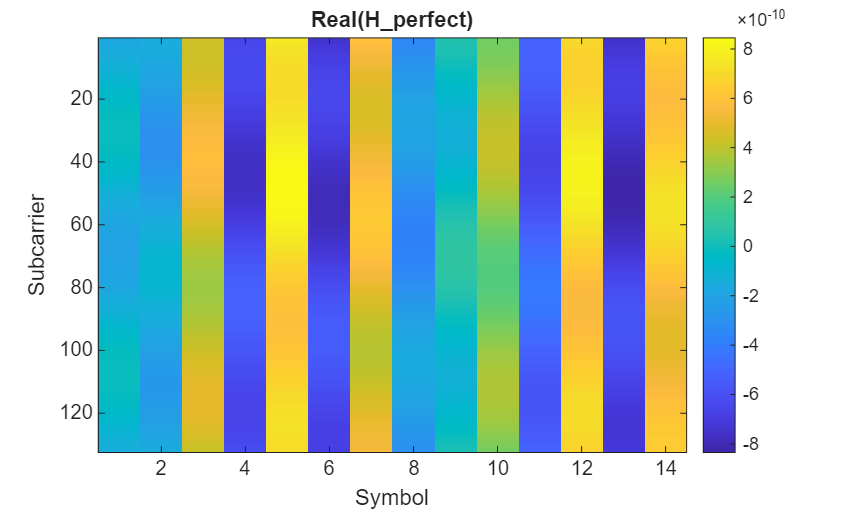

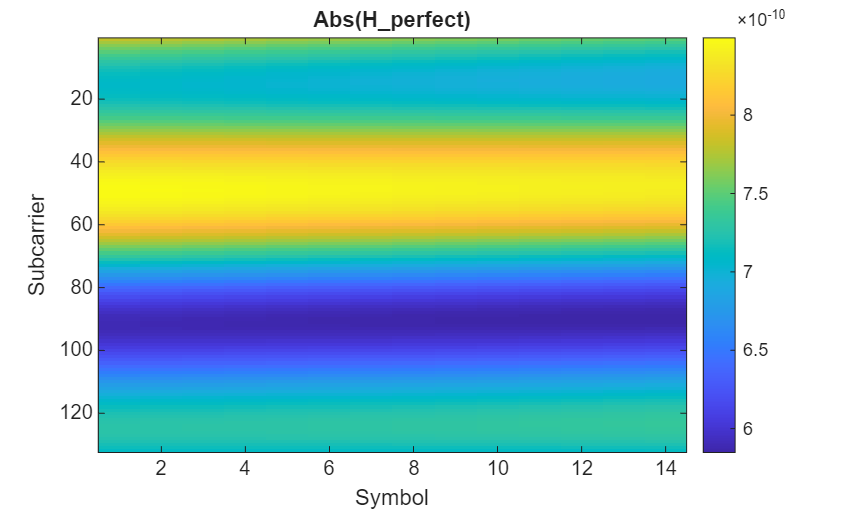

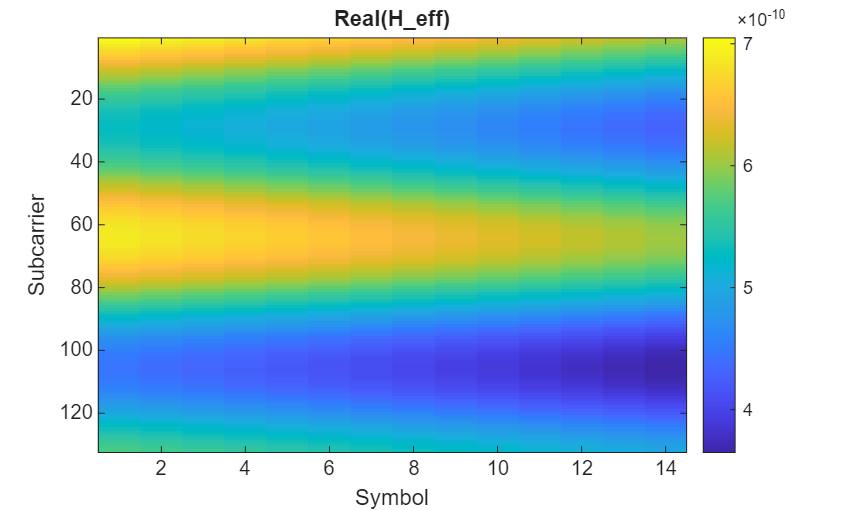

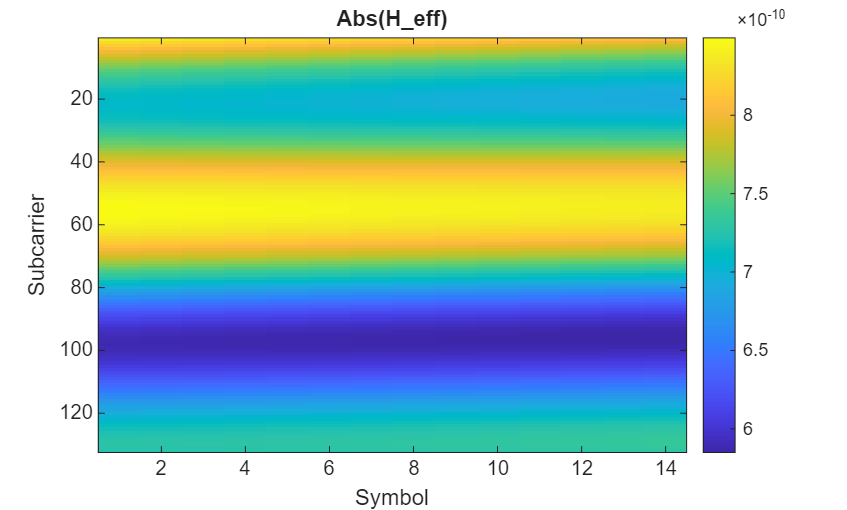

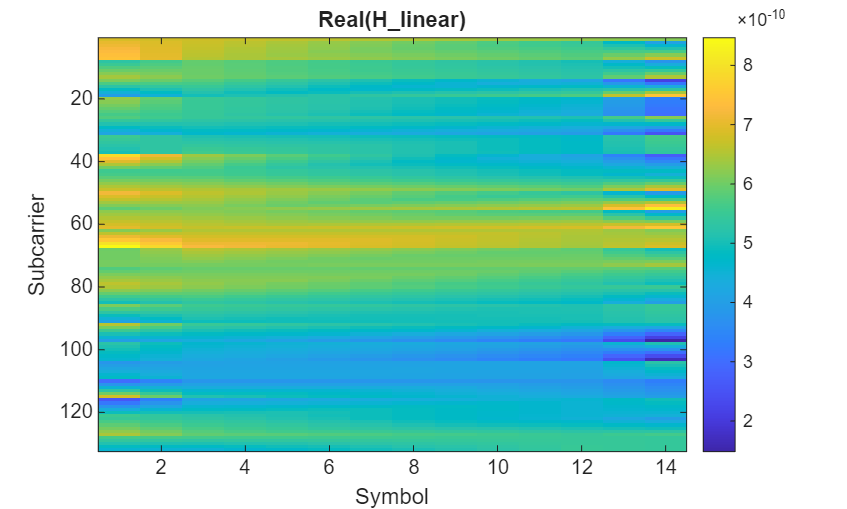

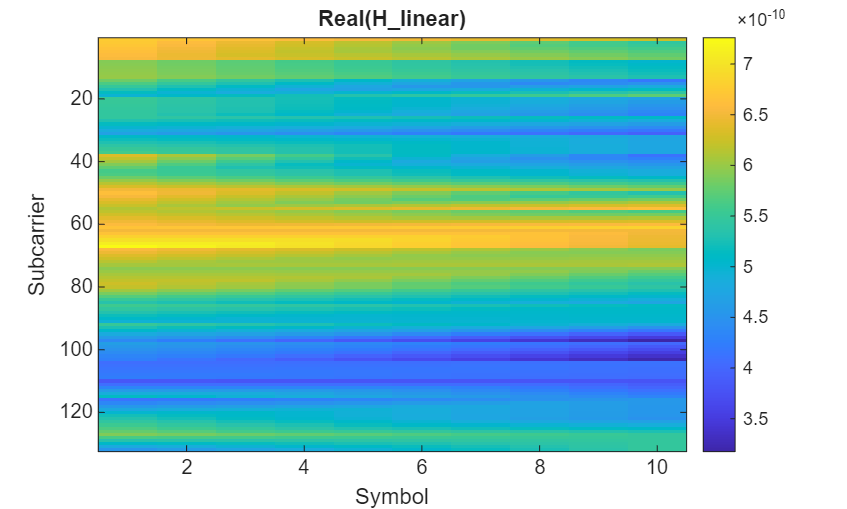

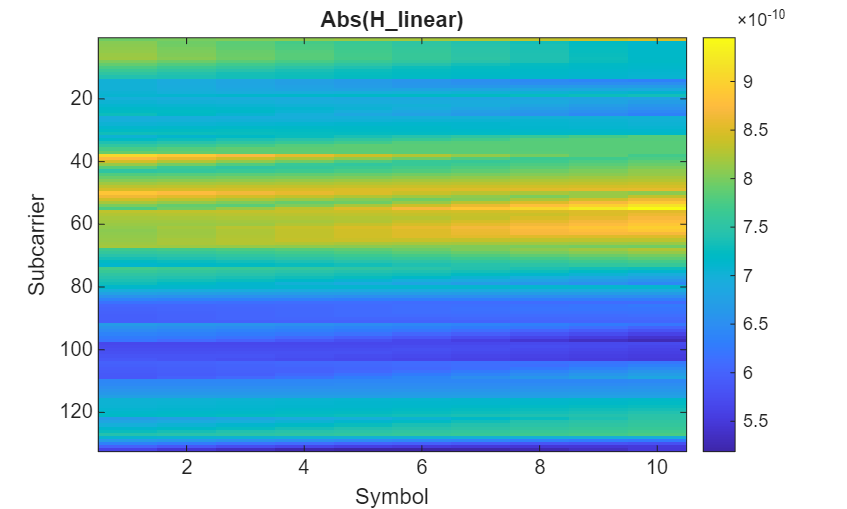

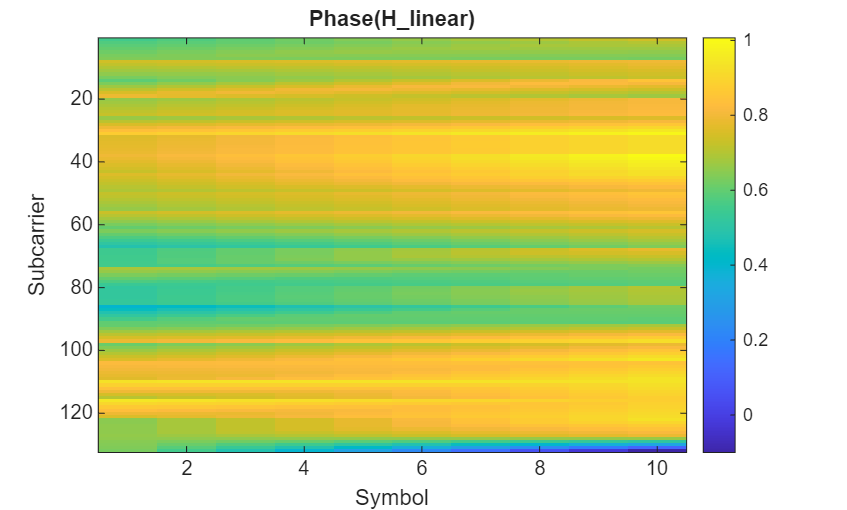

SNRdB = 10;
for idx = 1:2
    if channel.RandomStream == "Global stream"
        reset(channel);
    elseif channel.RandomStream == "mt19937ar with seed"
        release(channel);       % Unlocks the object so you can change its properties
        channel.Seed = idx;     % Assign a new, unique seed for each iteration
    end
    [rxWaveform2,pathGains] = channel(txWaveform2);
    pathFilters = getPathFilters(channel);
    offset = nrPerfectTimingEstimate(pathGains,pathFilters);
    rxGrid2 = nrOFDMDemodulate(carrier,rxWaveform2(1+offset:end,:)); %
    hEstPerfect2 = nrPerfectChannelEstimate(carrier,pathGains,pathFilters,offset); 
    hEstPerfect2 = hEstPerfect2 * db2mag(-pl_dB);
    H_eff = rxGrid2 * db2mag(-pl_dB);

    %%% Simplified transmission
    rxGrid_pilot = txGrid_pilot .* H_eff;
    %% Add noise
    % 1. Convert to linear
    SNR = 10^(SNRdB/10); % Convert to linear scale
    % 2. Calculate the average signal power (P_sig)
        % Use the pilot symbols since that's what we're transmitting
    % sigPower = mean(abs(rxGrid_pilot(refDMRSIndices)).^2, 'all');
     % SNR grid-wise
    sigPower = mean(abs(rxGrid_pilot(:)).^2, 'all');
    % 3. Calculate the required noise power (N_0)
    noisePower = sigPower / SNR;
    % 4. Generate complex white Gaussian noise
    % Noise power is distributed between Real and Imaginary parts (divide by 2)
    noise = sqrt(noisePower/2) * (randn(size(rxGrid_pilot)) + 1j*randn(size(rxGrid_pilot)));
    % 5. Add noise element-wise to the received grid
    rxGrid_pilot_noisy = rxGrid_pilot + noise;
    %%%
    
    % Least Square + Linear Interpolation
    [H_equalized_n, H_linear_n] = Lin_Interpolate(rxGrid_pilot_noisy, refDMRSIndices, refDMRSSymbols);
    [estChannelGrid,noiseEst] = nrChannelEstimate(carrier,rxGrid_pilot_noisy,...
            refDMRSIndices,refDMRSSymbols,'CDMLengths',pdsch.DMRS.CDMLengths);

    figure; imagesc(real(hEstPerfect2)); colorbar; title('Real(H\_perfect)')
    xlabel('Symbol'); ylabel('Subcarrier');
    
    figure; imagesc(abs(hEstPerfect2)); colorbar; title('Abs(H\_perfect)')
    xlabel('Symbol'); ylabel('Subcarrier');

    figure; imagesc(real(H_eff)); colorbar; title('Real(H\_eff)')
    xlabel('Symbol'); ylabel('Subcarrier');
    
    figure; imagesc(abs(H_eff)); colorbar; title('Abs(H\_eff)')
    xlabel('Symbol'); ylabel('Subcarrier');

    figure; imagesc(real(H_linear_n)); colorbar; title('Real(H\_linear)')
    xlabel('Symbol'); ylabel('Subcarrier');

    figure; imagesc(real(H_linear_n(:,3:12))); colorbar; title('Real(H\_linear)')
    xlabel('Symbol'); ylabel('Subcarrier');
    
    figure; imagesc(abs(H_linear_n(:,3:12))); colorbar; title('Abs(H\_linear)')
    xlabel('Symbol'); ylabel('Subcarrier');

    figure; imagesc(angle(H_linear_n(:,3:12))); colorbar; title('Phase(H\_linear)')
    xlabel('Symbol'); ylabel('Subcarrier');

    figure; imagesc(real(estChannelGrid)); colorbar; title('Real(H\_Practical)')
    xlabel('Symbol'); ylabel('Subcarrier');
    
    figure; imagesc(abs(estChannelGrid)); colorbar; title('Abs(H\_Practical)')
    xlabel('Symbol'); ylabel('Subcarrier');

    figure; imagesc(angle(estChannelGrid)); colorbar; title('Phase(H\_Practical)')
    xlabel('Symbol'); ylabel('Subcarrier');
end